Consider the following system with 3 dofs

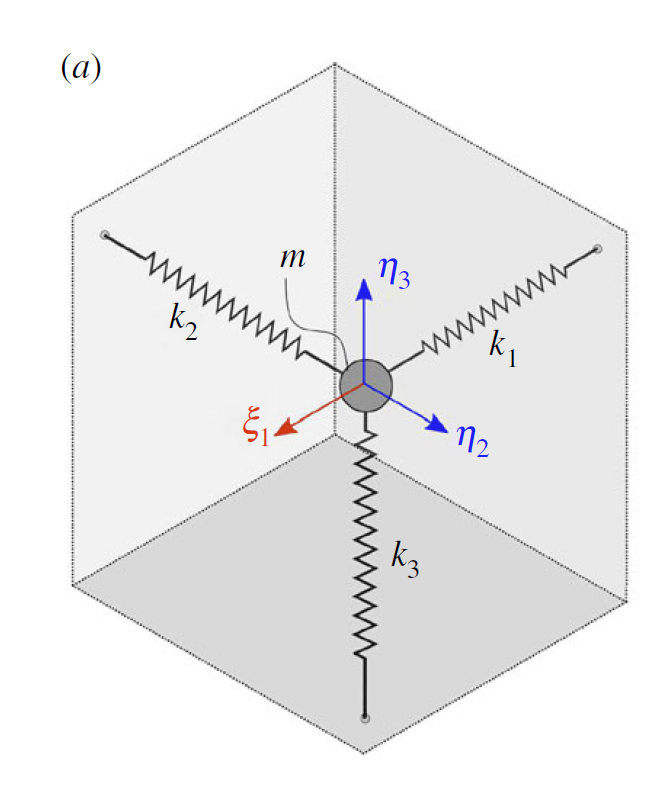reproduced from [1]

The equation of motion for the system is given by


$$\ddot{x}_1+2\zeta_1\omega_1\dot{x}_1+\omega_1^2x_1+\frac{\omega_1^2}{2}(3x_1^2+x_2^2 + x_3^2)+\omega_2^2x_1x_2+\omega_3^2x_1x_3+\frac{\omega_1^2+\omega_2^2 + \omega_3^2}{2}x_1(x_1^2+x_2^2+x_3^2)=\epsilon f_1\cos\Omega t,\\

\ddot{x}_2+2\zeta_2\omega_2\dot{x}_2+\omega_2^2x_2+\frac{\omega_2^2}{2}(3x_2^2+x_1^2 + x_3^2)+\omega_1^2x_1x_2+ \omega_3^2x_2 x_3 + \frac{\omega_1^2+\omega_2^2 + \omega_3^2}{2}x_2(x_1^2+x_2^2+ x_3^2)=0,\\
\ddot{x}_3+2\zeta_3\omega_3\dot{x}_3+\omega_3^2x_3+\frac{\omega_3^2}{2}(3x_3^2+x_1^2 + x_2^2)+\omega_1^2x_1x_3+ \omega_2^2x_2x_3 +\frac{\omega_1^2+\omega_2^2 + \omega_3^2}{2}x_3(x_1^2+x_2^2+ x_3^2)=0$$


Here we also consider a configuration constraint $g(x_1,x_2,x_3)=0$ that satisfies $g(0,0,0)=0$. The equation of motion is updated as

$\ddot{x}_1+2\zeta_1\omega_1\dot{x}_1+\omega_1^2x_1+\frac{\omega_1^2}{2}(3x_1^2+x_2^2 + x_3^2)+\omega_2^2x_1x_2+\omega_3^2x_1x_3+\frac{\omega_1^2+\omega_2^2 + \omega_3^2}{2}x_1(x_1^2+x_2^2+x_3^2)+\lambda \frac{\partial g(x_1,x_2,x_3)}{\partial{x_1}}=\epsilon f_1\cos\Omega t,\\
\ddot{x}_2+2\zeta_2\omega_2\dot{x}_2+\omega_2^2x_2+\frac{\omega_2^2}{2}(3x_2^2+x_1^2 + x_3^2)+\omega_1^2x_1x_2+ \omega_3^2x_2 x_3 + \frac{\omega_1^2+\omega_2^2 + \omega_3^2}{2}x_2(x_1^2+x_2^2+ x_3^2)+\lambda \frac{\partial g(x_1,x_2,x_3)}{\partial{x_2}}=0,\\
\ddot{x}_3+2\zeta_3\omega_3\dot{x}_3+\omega_3^2x_3+\frac{\omega_3^2}{2}(3x_3^2+x_1^2 + x_2^2)+\omega_1^2x_1x_3+ \omega_2^2x_2x_3 +\frac{\omega_1^2+\omega_2^2 + \omega_3^2}{2}x_3(x_1^2+x_2^2+ x_3^2)+\lambda \frac{\partial g(x_1,x_2,x_3)}{\partial{x_3}}=0,
g(x_1,x_2,x_3)=0.$We consider configuration constraint has the form


$$g(x_1,x_2,x_3)=x_1^2+x_2^2+(x_3-1)^2-1$$


which gives


$$\frac{\partial g(x_1,x_2,x_3)}{\partial{x_1}}=2x_1,\,\frac{\partial g(x_1,x_2,x_3)}{\partial{x_2}}=2x_2,\,\frac{\partial g(x_1,x_2,x_3)}{\partial{x_3}}=2(x_3-1).$$


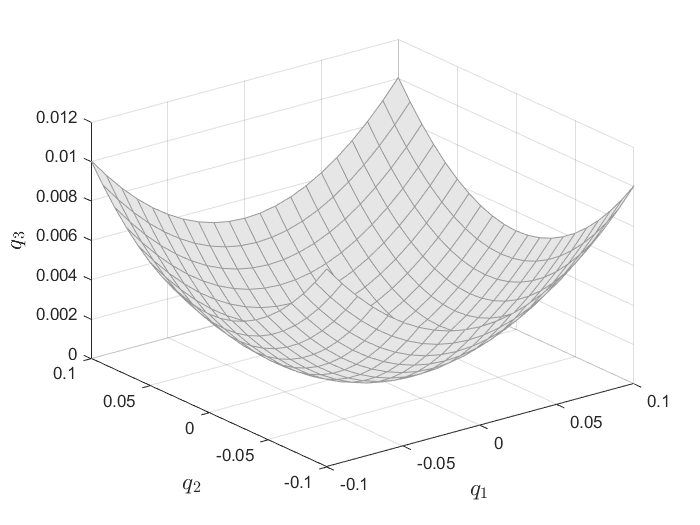

figure;
[q1,q2]=meshgrid(-0.1:0.01:0.1,-0.1:0.01:0.1);
surf(q1,q2,1-sqrt(1-q1.^2-q2.^2),'FaceColor', 0.9*[1 1 1], 'FaceAlpha', 1.0, ...
    'LineStyle', '-', 'EdgeColor', 0.6*[1 1 1], ...
    'LineWidth', 0.5);
xlabel('$q_1$','Interpreter',"latex",'FontSize',14);
ylabel('$q_2$','Interpreter',"latex",'FontSize',14);
zlabel('$q_3$','Interpreter',"latex",'FontSize',14);

Configuration constraint $x_1^2+x_2^2+(x_3-1)^2=1$

[1] Buza, G., Jain, S., & Haller, G. (2021). Using spectral submanifolds for optimal mode selection in nonlinear model reduction. *Proceedings of the Royal Society A*, *477*(2246), 20200725.

clear all

## Setup model

om1 = 2;
om2 = 3;
om3 = 5;
zeta1 = 0.01;
zeta2 = 0.05;
zeta3 = 0.05; %
f1    = 1;
[B,A,Fnl,Fext] = build_model(om1,om2,om3,zeta1,zeta2,zeta3,f1,'sphere');

DSorder = 1;
DS = DynamicalSystem(DSorder);
set(DS,'B',B,'A',A,'fnl',Fnl);
set(DS.Options,'Emax',8,'Nmax',10,'notation','multiindex')

**Linear Modal analysis**

[V,D,W] = DS.linear_spectral_analysis();

3 nan/inf eigenvalues are removed

 The first 4 nonzero eigenvalues are given as 
  -0.0200 + 1.9999i
  -0.0200 - 1.9999i
  -0.1500 + 2.9962i
  -0.1500 - 2.9962i



## Autonomous SSM 

S = SSM(DS);
set(S.Options, 'reltol', 1,'notation','multiindex');
resonant_modes = [1 2]; % choose master spectral subspace
order = 13;                  % SSM expansion order
S.choose_E(resonant_modes)

(near) outer resonance detected for the following combination of master eigenvalues
     2     0
     2     1
     3     1
     3     2
     4     2
     4     3
     0     2
     1     2
     1     3
     2     3
     2     4
     3     4

These are in resonance with the follwing eigenvalues of the slave subspace
  -0.1500 + 2.9962i
  -0.1500 + 2.9962i
  -0.1500 + 2.9962i
  -0.1500 + 2.9962i
  -0.1500 + 2.9962i
  -0.1500 + 2.9962i
  -0.1500 - 2.9962i
  -0.1500 - 2.9962i
  -0.1500 - 2.9962i
  -0.1500 - 2.9962i
  -0.1500 - 2.9962i
  -0.1500 - 2.9962i

sigma_out = 7
(near) inner resonance detected for the following combination of master eigenvalues
     2     1
     3     2
     4     3
     1     2
     2     3
     3     4

These are in resonance with the follwing eigenvalues of the master subspace
  -0.0200 + 1.9999i
  -0.0200 + 1.9999i
  -0.0200 + 1.9999i
  -0.0200 - 1.9999i
  -0.0200 - 1.9999i
  -0.0200 - 1.9999i

sigma_in = 7


[W0,R0] = S.compute_whisker(order);

Due to (near) outer resonance, the exisitence of the manifold is questionable and the underlying computation may suffer.
Attempting manifold computation
Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 1.56E-02 MB
Manifold computation time at order 3 = 00:00:00
Estimated memory usage at order  3 = 1.83E-02 MB
Manifold computation time at order 4 = 00:00:00
Estimated memory usage at order  4 = 2.15E-02 MB
Manifold computation time at order 5 = 00:00:00
Estimated memory usage at order  5 = 2.65E-02 MB
Manifold computation time at order 6 = 00:00:00
Estimated memory usage at order  6 = 3.26E-02 MB
Manifold computation time at order 7 = 00:00:00
Estimated memory usage at order  7 = 4.08E-02 MB
Manifold computation time at order 8 = 00:00:00
Estimated memory usage at order  8 = 5.06E-02 MB
Manifold computation time at order 9 = 00:00:00
Estimated memory usage at order  9 = 6.28E-02 MB
Manifold computation time at order 10 = 00:00:00
Estimated memory usage

#### Reduced dynamics in symbolic form

lamdMaster = DS.spectrum.Lambda(resonant_modes);
options = struct();
options.isauto = true; 
options.isdamped = false;
options.numDigits = 4;
y = reduced_dynamics_symbolic(lamdMaster,R0,options)

$$y = \left(\begin{array}{c} 1068.0\,{\rho_{1}}^{13}+26.99\,{\rho_{1}}^{11}+5.725\,{\rho_{1}}^{9}-1.945\,{\rho_{1}}^{7}+0.2779\,{\rho_{1}}^{5}-0.05085\,{\rho_{1}}^{3}-0.02\,\rho_{1}\\ 55620.0\,{\rho_{1}}^{12}-12060.0\,{\rho_{1}}^{10}+1341.0\,{\rho_{1}}^{8}-88.02\,{\rho_{1}}^{6}-3.666\,{\rho_{1}}^{4}+4.421\,{\rho_{1}}^{2}+2.0 \end{array}\right)$$

Symbolic string to latex 

% sympref('FloatingPointOutput',true);
% rho1dot = latex(y(1))
% theta1dot = latex(y(2))

Convergence of backbone curve

% 3.467*rho_1^6 - 8.963*rho_1^4 + 0.8168*rho_1^2 + 2.0
syms rho_1 positive
[coeffs,powers]=coeffs(y(2));
tmp = simplify(log(powers));
exp_idx = double(tmp./log(rho_1));

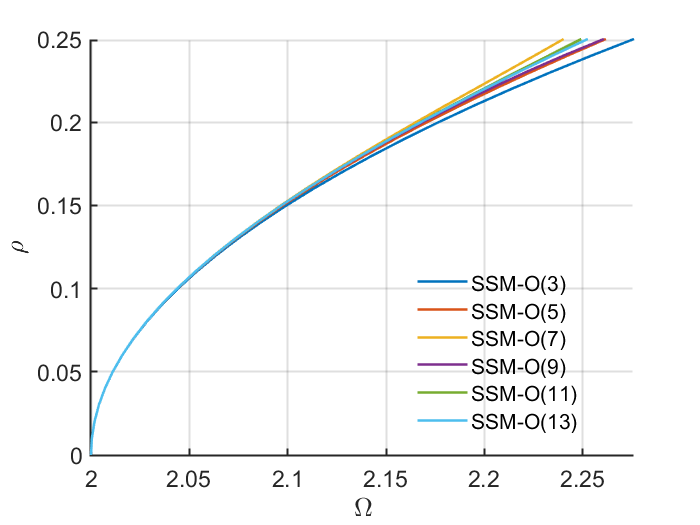

rhosamp = 0:0.01:0.25;
orders = [3 5 7 9 11 13];
plot_backbone_curves(double(coeffs),exp_idx,rhosamp,orders)

#### visualization of 2D SSM

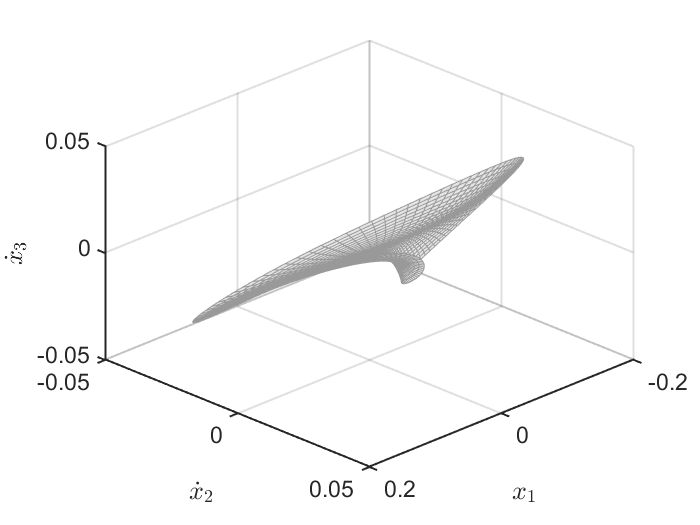

rhosamp = 0:0.01:0.25;
plotdofs = [1 5 6]; 
plot_2D_auto_SSM(W0,rhosamp,plotdofs,{'$x_1$','$\dot{x}_2$','$\dot{x}_3$'});

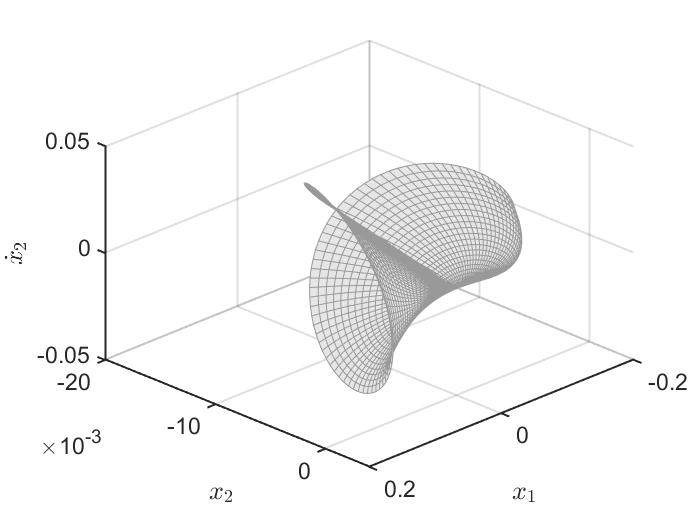

plotdofs = [1 2 5]; 
plot_2D_auto_SSM(W0,rhosamp,plotdofs,{'$x_1$','${x}_2$','$\dot{x}_2$'});

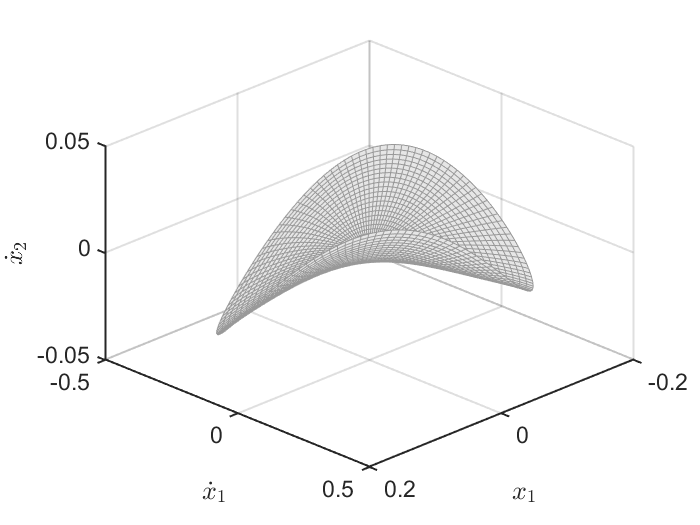

plotdofs = [1 4 5]; 
plot_2D_auto_SSM(W0,rhosamp,plotdofs,{'$x_1$','$\dot{x}_1$','$\dot{x}_2$'});

figssm = gcf;

#### Transient response validation

We take an initial condition on SSM and perform forward simulation using both the reduced-order model and the full model

tf = 50;
nsteps = 1000;
q0 = 0.24*exp(1i*0.5);
q0 = [q0;conj(q0)];
z0 = reduced_to_full_traj(0,q0,W0);
traj = transient_traj_on_auto_ssm(DS, resonant_modes, W0, R0, tf, nsteps, 1:6, [], q0);

Reference solution from forward simulation

options = odeset('RelTol',1e-8,'AbsTol',1e-10);
epf = 0; omega = 2*pi; 
psp = [epf; omega];
[tInt1, zInt1] = ode15s(@(t,x) spring_ode(t,x,psp,'sphere'), [0 tf], z0(1:6),options); % Transients

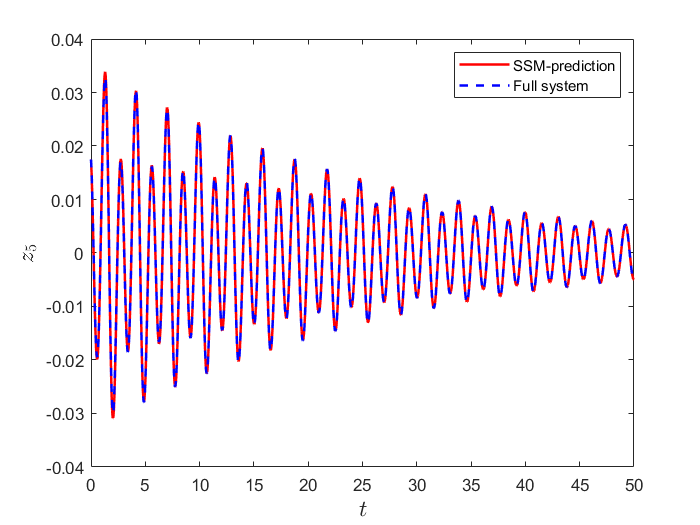

figure;
plot(traj.time,traj.phy(:,5),'r-','LineWidth',1.5); hold on
plot(tInt1,zInt1(:,5),'b--','LineWidth',1.5);
legend('SSM-prediction','Full system')
xlabel('$t$','Interpreter',"latex",'FontSize',14);
ylabel('$z_5$','Interpreter',"latex",'FontSize',14);

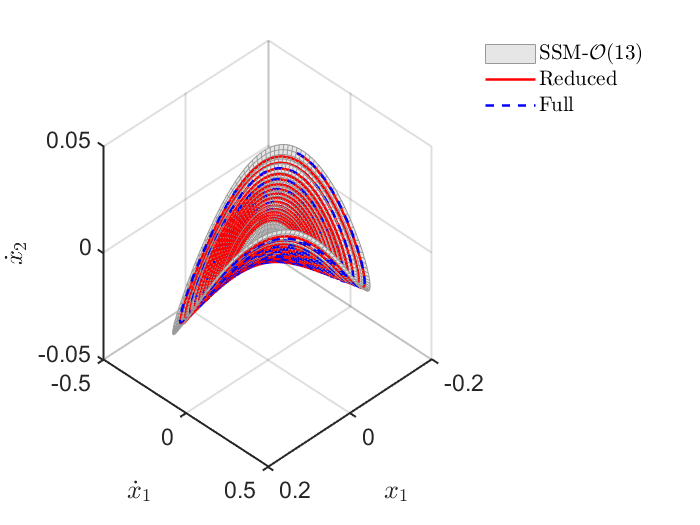

figure(figssm); hold on
hold on
plot3(traj.phy(:,plotdofs(1)),traj.phy(:,plotdofs(2)),traj.phy(:,plotdofs(3)),'r-','LineWidth',1.5);
plot3(zInt1(:,plotdofs(1)),zInt1(:,plotdofs(2)),zInt1(:,plotdofs(3)),'b--','LineWidth',1.5);
legend('SSM-$\mathcal{O}(13)$','Reduced','Full','interpreter','latex');
legend boxoff

#### Transient response prediction

tf = 50;
nsteps = 1000;
z0 = 0.1*[1 0.1 0.2 1 0.0 0.1 0]';
% consistent initial condition
z0(3) = 1-sqrt(1-z0(1)^2-z0(2)^2);
z0(6) = -(z0(1)*z0(4)+z0(2)*z0(5))/(z0(3)-1);
z0(7) = lambda_constraints(0,z0(1:6),[0;1],'sphere');
traj = transient_traj_on_auto_ssm(DS, resonant_modes, W0, R0, tf, nsteps, 1:6, z0);

Reference solution from forward simulation

options = odeset('RelTol',1e-8,'AbsTol',1e-10);
epf = 0; omega = 2*pi; 
psp = [epf; omega];
[tInt, zInt] = ode15s(@(t,x) spring_ode(t,x,psp,'sphere'), [0 tf], z0(1:6),options); % Transients

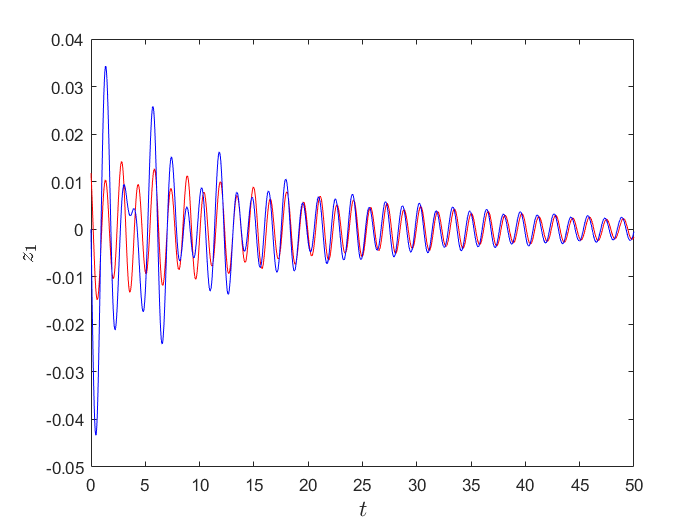

figure;
plot(traj.time,traj.phy(:,5),'r-'); hold on
plot(tInt,zInt(:,5),'b-');
xlabel('$t$','Interpreter',"latex",'FontSize',14);
ylabel('$z_1$','Interpreter',"latex",'FontSize',14);

#### Visualization of 2D SSM

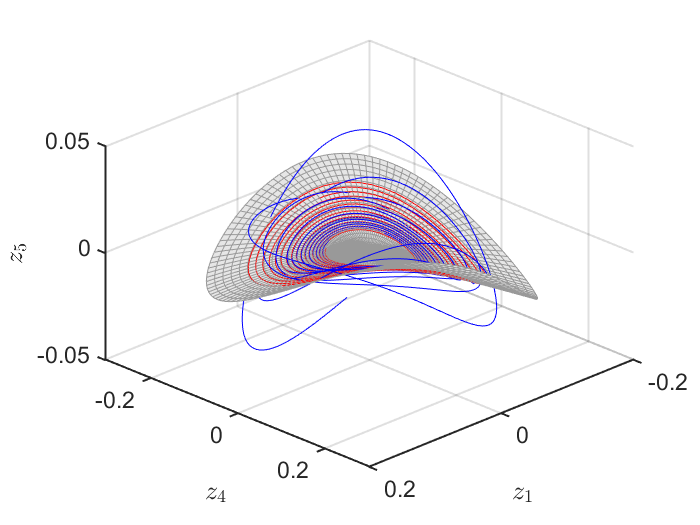

rhosamp = 0:0.01:0.2;
plotdofs = [1 4 5];
plot_2D_auto_SSM(W0,rhosamp,plotdofs);
hold on
plot3(traj.phy(:,plotdofs(1)),traj.phy(:,plotdofs(2)),traj.phy(:,plotdofs(3)),'r-');
plot3(zInt(:,plotdofs(1)),zInt(:,plotdofs(2)),zInt(:,plotdofs(3)),'b-');

Plot configuration constraints

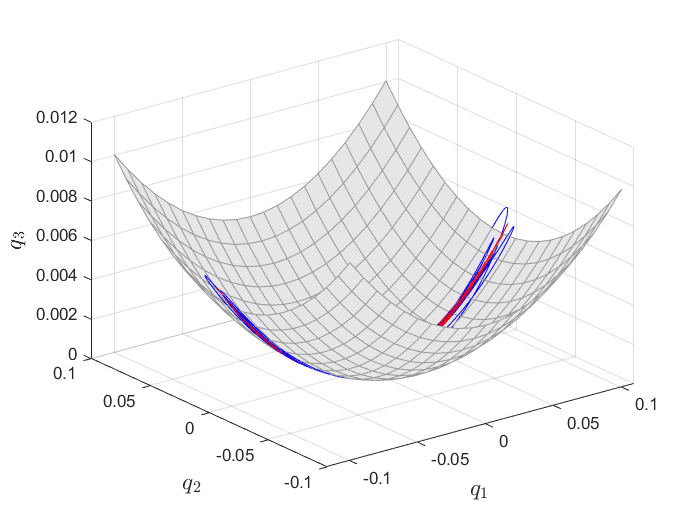

figure;
[q1,q2]=meshgrid(-0.1:0.01:0.1,-0.1:0.01:0.1);
surf(q1,q2,1-sqrt(1-q1.^2-q2.^2),'FaceColor', 0.9*[1 1 1], 'FaceAlpha', 1.0, ...
    'LineStyle', '-', 'EdgeColor', 0.6*[1 1 1], ...
    'LineWidth', 0.5);
hold on
plot3(traj.phy(:,1),traj.phy(:,2),traj.phy(:,3),'r-');
plot3(zInt(:,1),zInt(:,2),zInt(:,3),'b-');
xlabel('$q_1$','Interpreter',"latex",'FontSize',14);
ylabel('$q_2$','Interpreter',"latex",'FontSize',14);
zlabel('$q_3$','Interpreter',"latex",'FontSize',14);

#### Backbone curve 

#### SSM prediction

(near) outer resonance detected for the following combination of master eigenvalues
     2     0
     2     1
     3     1
     3     2
     4     2
     4     3
     0     2
     1     2
     1     3
     2     3
     2     4
     3     4

These are in resonance with the follwing eigenvalues of the slave subspace
  -0.1500 + 2.9962i
  -0.1500 + 2.9962i
  -0.1500 + 2.9962i
  -0.1500 + 2.9962i
  -0.1500 + 2.9962i
  -0.1500 + 2.9962i
  -0.1500 - 2.9962i
  -0.1500 - 2.9962i
  -0.1500 - 2.9962i
  -0.1500 - 2.9962i
  -0.1500 - 2.9962i
  -0.1500 - 2.9962i

sigma_out = 7
(near) inner resonance detected for the following combination of master eigenvalues
     2     1
     3     2
     4     3
     1     2
     2     3
     3     4

These are in resonance with the follwing eigenvalues of the master subspace
  -0.0200 + 1.9999i
  -0.0200 + 1.9999i
  -0.0200 + 1.9999i
  -0.0200 - 1.9999i
  -0.0200 - 1.9999i
  -0.0200 - 1.9999i

sigma_in = 7
Due to (near) outer resonance, the exisitence of the man

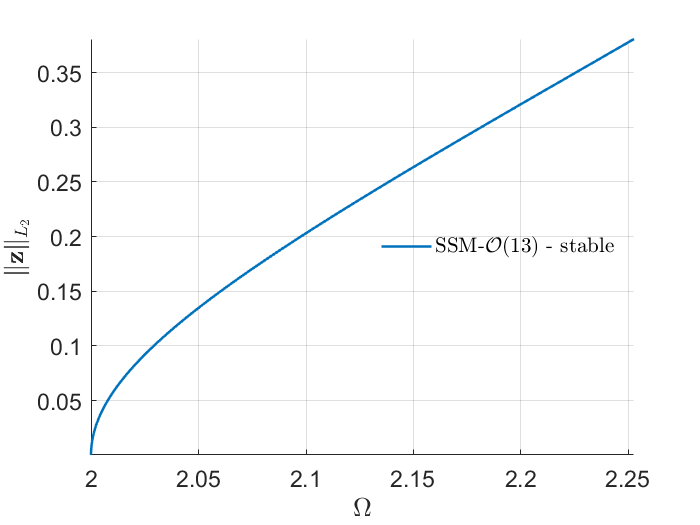

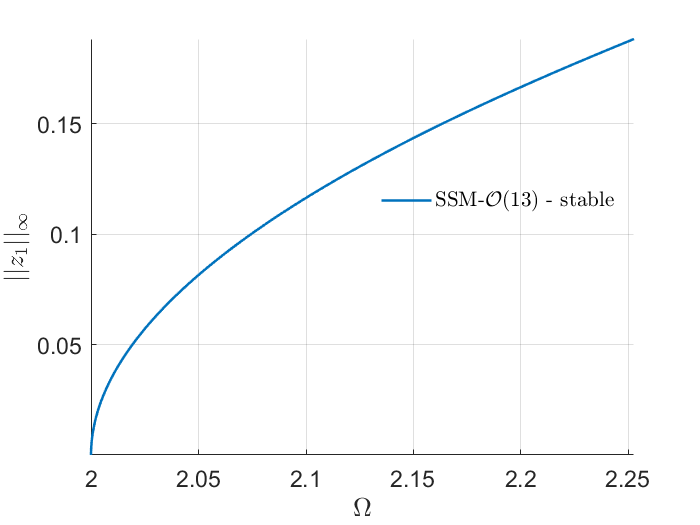

Total time spent on backbone curve computation = 00:00:02


set(S.FRCOptions,'outDOF',1);
freqRange = [1.95 2.3];
rhomax = 0.25;
BB = S.extract_backbone(resonant_modes, freqRange, order, rhomax);

figbc = gcf;

% THE PFF should be the same as SSM if the invariance relation is satisfied
% [amp,freq,damp,time] = PFF(tInt1,zInt1(:,1));
% hold on;
% plot(2*pi*freq,amp,'k*')

#### Backbone curve in conservative limit (using COCO)

options = odeset('RelTol',1e-8,'AbsTol',1e-10,'Events',@zero_crossing_event);
zeta = 0;
[tauto, xauto,te,ye] = ode15s(@(t,x) spring_ode_auto(x,zeta,'sphere'), [0 10], traj.phy(end,:)',options);   % Approximate periodic orbit

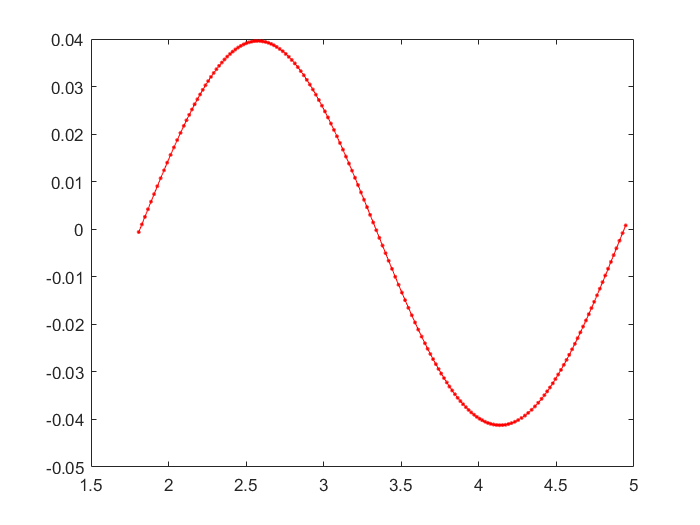

[~,idx1] = min(abs(tauto-te(1)));
[~,idx2] = min(abs(tauto-te(2)));
figure;
plot(tauto(idx1:idx2),xauto(idx1:idx2,1),'r.-');

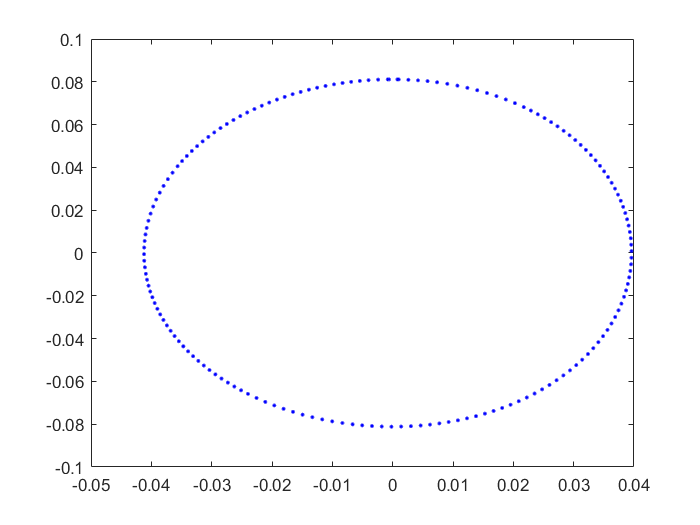

figure
plot(xauto(idx1:idx2,1),xauto(idx1:idx2,4),'b.');

Continuation of periodic orbits with po-toolbox of COCO

prob = coco_prob();
prob = coco_set(prob, 'cont', 'NAdapt', 2);
% prob = coco_set(prob, 'cont', 'NAdapt', 5, 'h_max', 50, 'PtMX', 250);
prob = coco_set(prob, 'coll', 'NTST', 10);
prob = coco_set(prob, 'po', 'bifus', 'off');
odefun = @(x,p) spring_ode_auto(x,p,'sphere');
funcs  = {odefun};
coll_args = [funcs, {tauto(idx1:idx2)-tauto(idx1), xauto(idx1:idx2,:), {'zeta'}, 0}];
prob = ode_isol2po(prob, '', coll_args{:});
[data, uidx] = coco_get_func_data(prob, 'po.orb.coll', 'data', 'uidx');
maps = data.coll_seg.maps;
ampdata.dof  = 1;
ampdata.zdim = 6;
prob = coco_add_func(prob, 'amp1', @amplitude, ampdata, 'regular', 'x1',...
    'uidx', uidx(maps.xbp_idx), 'remesh', @amplitude_remesh);
ampdata.dof  = 2;
prob = coco_add_func(prob, 'amp2', @amplitude, ampdata, 'regular', 'x2',...
    'uidx', uidx(maps.xbp_idx), 'remesh', @amplitude_remesh);

Tmin = 2*pi/max([BB.Omega]);
Tmax = 2*pi/min([BB.Omega]);
cont_args = {1, {'zeta' 'po.period' 'x1' 'x2'}, {[],[Tmin,1.1*Tmax]}};

fprintf('\n Run=''%s'': Continue primary family of periodic orbits.\n', ...
  'backbone_coco');


 Run='backbone_coco': Continue primary family of periodic orbits.



bd0  = coco(prob, 'backbone_coco', [], cont_args{:});


    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          1.41e-03  4.46e+00    0.0    0.0    0.0
   1   1  1.00e+00  2.45e-02  9.12e-06  4.44e+00    0.0    0.0    0.0
   2   1  1.00e+00  2.05e-04  5.89e-10  4.44e+00    0.0    0.0    0.0
   3   1  1.00e+00  1.58e-08  1.90e-16  4.44e+00    0.0    0.0    0.0

 STEP      TIME        ||U||  LABEL  TYPE          zeta    po.period           x1           x2
    0  00:00:00   4.4371e+00      1  EP     -3.9228e-10   3.1214e+00   4.0792e-02   9.0439e-04
    4  00:00:01   4.4425e+00      2  BP      3.1343e-11   3.1406e+00   9.0564e-03   4.6412e-05
   10  00:00:02   4.5337e+00      3  EP      1.9782e-09   2.7892e+00   1.8774e-01   1.4062e-02

 STEP      TIME        ||U||  LABEL  TYPE          zeta    po.period           x1           x2
    0  00:00:02   4.4371e+00      4  EP     -3.9228e-10   3.1214e+00   4.0792e-02   9.0439e-04
    6  

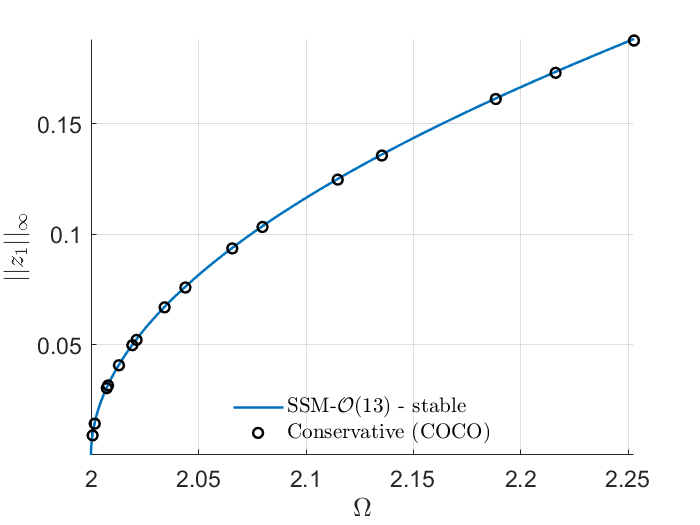

figure(figbc); hold on
% plot([BB.Omega],[BB.Aout],'b-'); hold on
bd = coco_bd_read('backbone_coco');
amp_auto_coco = coco_bd_col(bd,'x1');
om_auto_coco = 2*pi./coco_bd_col(bd,'po.period');
plot(om_auto_coco,amp_auto_coco,'ko','LineWidth',1.5,'MarkerSize',6,'DisplayName','Conservative (COCO)')

## Non-autonomous -  forced response curve

Add forcing

epsilon = 0.015;
kappas = [1; -1];
coeffs = [Fext Fext]/2;
DS.add_forcing(coeffs, kappas, epsilon);

## SSM computation

S = SSM(DS);
set(S.Options, 'reltol', 1,'notation','multiindex');
% resonant_modes = [1 2]; % choose master spectral subspace
outdof = 1;             % outdof

*****************************************
Calculating FRC using SSM with master subspace: [1  2]
(near) outer resonance detected for the following combination of master eigenvalues
     2     0
     2     1
     3     1
     3     2
     4     2
     4     3
     0     2
     1     2
     1     3
     2     3
     2     4
     3     4

These are in resonance with the follwing eigenvalues of the slave subspace
  -0.1500 + 2.9962i
  -0.1500 + 2.9962i
  -0.1500 + 2.9962i
  -0.1500 + 2.9962i
  -0.1500 + 2.9962i
  -0.1500 + 2.9962i
  -0.1500 - 2.9962i
  -0.1500 - 2.9962i
  -0.1500 - 2.9962i
  -0.1500 - 2.9962i
  -0.1500 - 2.9962i
  -0.1500 - 2.9962i

sigma_out = 7
(near) inner resonance detected for the following combination of master eigenvalues
     2     1
     3     2
     4     3
     1     2
     2     3
     3     4

These are in resonance with the follwing eigenvalues of the master subspace
  -0.0200 + 1.9999i
  -0.0200 + 1.9999i
  -0.0200 + 1.9999i
  -0.0200 - 1.9999i
  -0.0200 - 1

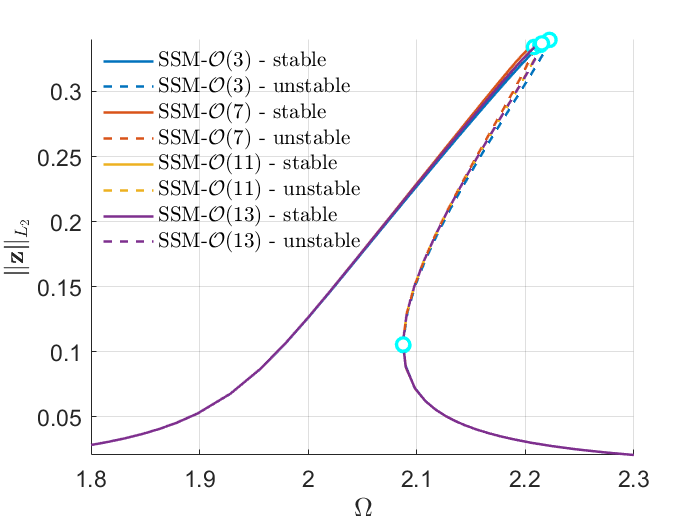

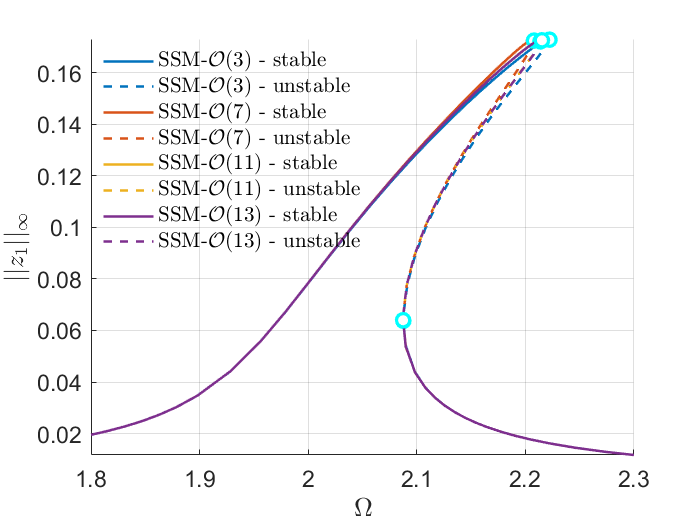

*****************************************
Calculating FRC using SSM with master subspace: [1  2]
(near) outer resonance detected for the following combination of master eigenvalues
     2     0
     2     1
     3     1
     3     2
     4     2
     4     3
     0     2
     1     2
     1     3
     2     3
     2     4
     3     4

These are in resonance with the follwing eigenvalues of the slave subspace
  -0.1500 + 2.9962i
  -0.1500 + 2.9962i
  -0.1500 + 2.9962i
  -0.1500 + 2.9962i
  -0.1500 + 2.9962i
  -0.1500 + 2.9962i
  -0.1500 - 2.9962i
  -0.1500 - 2.9962i
  -0.1500 - 2.9962i
  -0.1500 - 2.9962i
  -0.1500 - 2.9962i
  -0.1500 - 2.9962i

sigma_out = 7
(near) inner resonance detected for the following combination of master eigenvalues
     2     1
     3     2
     4     3
     1     2
     2     3
     3     4

These are in resonance with the follwing eigenvalues of the master subspace
  -0.0200 + 1.9999i
  -0.0200 + 1.9999i
  -0.0200 + 1.9999i
  -0.0200 - 1.9999i
  -0.0200 - 1

set(S.FRCOptions, 'initialSolver', 'fsolve','outdof',outdof);     % initial solution scheme
set(S.contOptions, 'PtMX', 200, 'h_max', 0.1);               % continuation setting
set(S.FRCOptions, 'method', 'continuation ep','p0',[],'z0',[]);
freqRange = [1.8 2.3];
epsRange  = [0.01 3]*epsilon;
S.extract_FRC('freq',freqRange,[3 7 11 13]);

figssm = gcf;

## Validation

A general form of DAE above is given by

$M\ddot{q}+G^\top \lambda=F(t,q,\dot{q}),\quad g(q)=0$.

Differentiate the configuration constraint twice yields

$G\dot{q}=0,\quad G\ddot{q}+\dot{G}\dot{q}=0$ and hence $G\ddot{q}=c$. 

We have


$$\left\lbrack \begin{array}{cc}
M & G^T \\
G & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\ddot{x} \\
\lambda \;
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
F\\
c
\end{array}\right\rbrack$$


from which we obtain


$$\lambda=-(GM^{-1}G^\top)^{-1}\left(c-GM^{-1}F\right)$$


and

$M\ddot{q}=F+G^\top (GM^{-1}G^\top)^{-1}(c-GM^{-1}F)$.

In this example, we have

$G=2[q_1,q_2,q_3-1]$, $GM^{-1}G^\top=4$, $c=-\dot{G}\dot{q}=-2(\dot{q}_1^2+\dot{q}_2^2+\dot{q}_3^2)$, $c-GM^{-1}F=c-2 q_1\,F_1-2 q_2\,F_2-2(q_3-1)F_3$ 

and then

$G^\top (GM^{-1}G^\top)^{-1}(c-GM^{-1}F)=\frac{c-2 q_1\,F_1-2 q_2\,F_2-2(q_3-1)F_3}{4} G^\top$.

Forward simulation of transformed system

options = odeset('RelTol',1e-8,'AbsTol',1e-10);
epf = epsilon; omega = 2; T = 2*pi/omega;
psp = [epf; omega];
[~, x0] = ode15s(@(t,x) spring_ode(t,x,psp,'sphere'), [0 200*T], zeros(6,1),options); % Transients
[ttor, xtor] = ode15s(@(t,x) spring_ode(t,x,psp,'sphere'), [0 T], x0(end,:)',options);   % Approximate periodic orbit

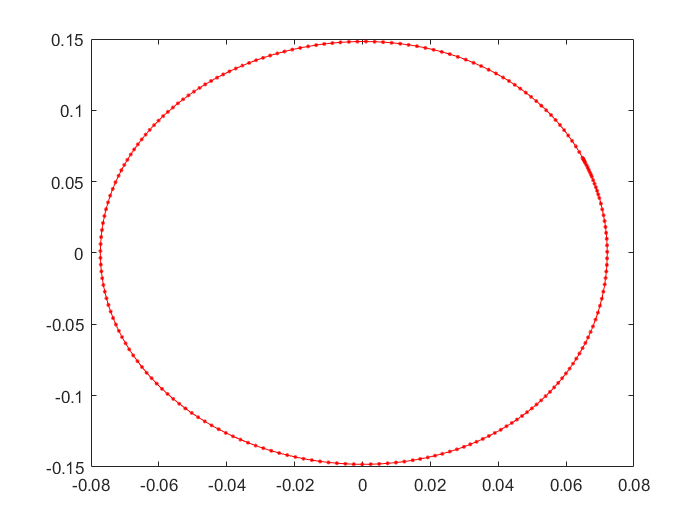

figure;
plot(xtor(:,1),xtor(:,4),'r.-')

Continuation of periodic orbits with po-toolbox of COCO

prob = coco_prob();
prob = coco_set(prob, 'ode', 'autonomous', false);
prob = coco_set(prob, 'cont', 'NAdapt', 2);
% prob = coco_set(prob, 'coll', 'NTST', 20);
odefun = @(t,x,p) spring_ode(t,x,p,'sphere');
funcs = {odefun};
coll_args = [funcs, {ttor, xtor, {'eps' 'Omega'}, psp}];
prob = ode_isol2po(prob, '', coll_args{:});
[data, uidx] = coco_get_func_data(prob, 'po.orb.coll', 'data', 'uidx');
maps = data.coll_seg.maps;
prob = coco_add_func(prob, 'OmegaT', @OmegaT, @OmegaT_du, [], 'zero',...
    'uidx', [uidx(maps.T_idx), uidx(maps.p_idx(2))]);
ampdata.dof  = 1;
ampdata.zdim = 6;
prob = coco_add_func(prob, 'amp1', @amplitude, ampdata, 'regular', 'x1',...
    'uidx', uidx(maps.xbp_idx), 'remesh', @amplitude_remesh);
ampdata.dof  = 2;
prob = coco_add_func(prob, 'amp2', @amplitude, ampdata, 'regular', 'x2',...
    'uidx', uidx(maps.xbp_idx), 'remesh', @amplitude_remesh);

cont_args = {1, {'Omega' 'po.period' 'x1' 'x2' 'eps'}, freqRange};

fprintf('\n Run=''%s'': Continue primary family of periodic orbits.\n', ...
  'freq_resp');


 Run='freq_resp': Continue primary family of periodic orbits.



bd1  = coco(prob, 'sphere_freq_resp', [], cont_args{:});


    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          1.10e-04  5.33e+00    0.0    0.0    0.0
   1   1  1.00e+00  7.62e-05  3.98e-10  5.33e+00    0.0    0.0    0.0
   2   1  1.00e+00  7.48e-09  4.03e-16  5.33e+00    0.0    0.0    0.0

 STEP      TIME        ||U||  LABEL  TYPE         Omega    po.period           x1           x2          eps
    0  00:00:00   5.3291e+00      1  EP      2.0000e+00   3.1416e+00   7.6983e-02   3.2533e-03   1.5000e-02
   10  00:00:01   5.4560e+00      2          1.8623e+00   3.3739e+00   2.6990e-02   5.0229e-04   1.5000e-02
   14  00:00:01   5.5568e+00      3  EP      1.8000e+00   3.4907e+00   1.9410e-02   2.9683e-04   1.5000e-02

 STEP      TIME        ||U||  LABEL  TYPE         Omega    po.period           x1           x2          eps
    0  00:00:01   5.3291e+00      4  EP      2.0000e+00   3.1416e+00   7.6983e-02   3.2533e-03   1.5000e-02

Plot results

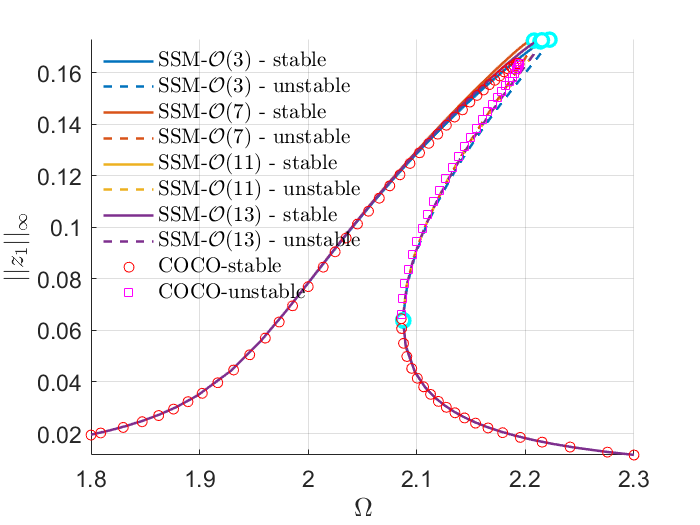

figure(figssm); hold on
omcoco = coco_bd_col(bd1,'Omega'); x1coco = coco_bd_col(bd1,'x1');
eigcoco = coco_bd_col(bd1,'eigs'); stab = all(abs(eigcoco)<1,1);
plot(omcoco(stab),x1coco(stab),'ro','DisplayName','COCO-stable');
plot(omcoco(~stab),x1coco(~stab),'ms','DisplayName','COCO-unstable');